%%%%%%%%%%%%%%%%%%%%%%
%%%figures that compare primary vs. QA, labs, and QA
%%%created:11/3/22
%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

%%ppb data, including data with all flags
% pre-allocate structures
ppbSDK = struct();
ppbSTER = struct();
ppbSSG = struct();
ppbCOV = struct();

%SDK
ppbSDK.base = readtimetable("ppb SDK.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSDK.noLK = readtimetable("ppb SDK.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSDK.noHg = readtimetable("ppb SDK.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");
ppbSDK.ATEC = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC", "VariableNamingRule", "preserve");
ppbSDK.ATECnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC no LK", "VariableNamingRule", "preserve");
ppbSDK.ATECnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC no 0 Hg", "VariableNamingRule", "preserve");
ppbSDK.Ent = readtimetable("ppb SDK.xlsx", "Sheet", "Ent", "VariableNamingRule", "preserve");
ppbSDK.EntnoLK = readtimetable("ppb SDK.xlsx", "Sheet", "Ent no LK", "VariableNamingRule", "preserve");
ppbSDK.EntnoHg = readtimetable("ppb SDK.xlsx", "Sheet", "Ent no 0 Hg", "VariableNamingRule", "preserve");
ppbSDK.Picarro = readtimetable("ppb SDK.xlsx", "Sheet", "Picarro", "VariableNamingRule", "preserve");
ppbSDK.PicarroDailyAvg = readtimetable("ppb SDK.xlsx", "Sheet", "Picarro daily avg", ...
    "VariableNamingRule", "preserve");
ppbSDK.PicarroDailyStd = readtimetable("ppb SDK.xlsx", "Sheet", "Picarro daily std", ...
    "VariableNamingRule", "preserve");
ppbSDK.AROMA = readtimetable("ppb SDK.xlsx", "Sheet", "AROMA", "VariableNamingRule", "preserve");
ppbSDK.AROMADailyAvg = readtimetable("ppb SDK.xlsx", "Sheet", "AROMA daily avg", ...
    "VariableNamingRule", "preserve");
ppbSDK.AROMADailyStd = readtimetable("ppb SDK.xlsx", "Sheet", "AROMA daily std", ...
    "VariableNamingRule", "preserve");

%STER
ppbSTER.base = readtimetable("ppb STER.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSTER.noLK = readtimetable("ppb STER.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSTER.noHg = readtimetable("ppb STER.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%SSG
ppbSSG.base = readtimetable("ppb SSG.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbSSG.noLK = readtimetable("ppb SSG.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbSSG.noHg = readtimetable("ppb SSG.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%COV
ppbCOV.base = readtimetable("ppb COV.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ppbCOV.noLK = readtimetable("ppb COV.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ppbCOV.noHg = readtimetable("ppb COV.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

cd ../../..

%%%%%%%%%%%%%%%%%%%%%%
%%%switch easily between flagged and unflagged data
%%%%%%%%%%%%%%%%%%%%%%

% pre-allocate structure
data = struct();

% change the data loaded when testing flagged data
data.SDKEnt = ppbSDK.Ent; % SDK passive
data.SDKATEC = ppbSDK.ATEC; % SDK pressurized
data.SDKPicarroDailyAvg = ppbSDK.PicarroDailyAvg;
data.SDKPicarroDailyStd = ppbSDK.PicarroDailyStd;
data.SDKAROMADailyAvg = ppbSDK.AROMADailyAvg;
data.SDKAROMADailyStd = ppbSDK.AROMADailyStd;
data.STER = ppbSTER.base; % STER
data.SSG = ppbSSG.base; % SSG
data.COV = ppbCOV.base; % COV

%%%%%%%%%%%%%%%%%%%%%%
%%%primary vs. collocated (QA)
%%%%%%%%%%%%%%%%%%%%%%

%%assemble TT
dataToCompare = struct(); % pre-allocate structure
dataToCompare.SDKEntPrimary = data.SDKEnt(:, [1, 2, 5]); %SDK passive primary
dataToCompare.SDKEntQA = data.SDKEnt(:, [4, 3, 6]); %SDK passive QA
dataToCompare.SDKATECPrimary = data.SDKATEC(:, [1, 3, 5]); %SDK pressurized primary
dataToCompare.SDKATECQA = data.SDKATEC(:, [2, 4, 6]); %SDK pressurized QA
dataToCompare.STERPrimary = data.STER(:, [1, 3, 5, 7]); %STER primary
dataToCompare.STERQA = data.STER(:, [2, 4, 6, 8]); %STER QA
dataToCompare.SSGPrimary = data.SSG(:, [1, 3, 6]); %SSG primary
dataToCompare.SSGQA = data.SSG(:, [2, 4, 7]); %SSG QA
dataToCompare.COVPrimary = data.COV(:, [2, 4, 6, 8]); %COV primary
dataToCompare.COVQA = data.COV(:, [3, 5, 7, 9]); %COV QA

%%unravel and prepare data for plotting [primary, QA]
dataUnravel = struct(); % pre-allocate structure
dataUnravel.SDKEnt = [unravelTTnan(dataToCompare.SDKEntPrimary), ...
    unravelTTnan(dataToCompare.SDKEntQA)]; %SDK passive
dataUnravel.SDKEnt(any(isnan(dataUnravel.SDKEnt), 2), :) = []; % remove non-matches

dataUnravel.SDKATEC = [unravelTTnan(dataToCompare.SDKATECPrimary), ...
    unravelTTnan(dataToCompare.SDKATECQA)]; %SDK pressurized
dataUnravel.SDKATEC(any(isnan(dataUnravel.SDKATEC), 2), :) = []; % remove non-matches

dataUnravel.STER = [unravelTTnan(dataToCompare.STERPrimary), ...
    unravelTTnan(dataToCompare.STERQA)]; %STER
dataUnravel.STER(any(isnan(dataUnravel.STER), 2), :) = []; % remove non-matches

dataUnravel.SSG = [unravelTTnan(dataToCompare.SSGPrimary), ...
    unravelTTnan(dataToCompare.SSGQA)]; %SSG
dataUnravel.SSG(any(isnan(dataUnravel.SSG), 2), :) = []; % remove non-matches

dataUnravel.COV = [unravelTTnan(dataToCompare.COVPrimary), ...
    unravelTTnan(dataToCompare.COVQA)]; %COV
dataUnravel.COV(any(isnan(dataUnravel.COV), 2), :) = []; % remove non-matches

%% calculate comparison statistics between primary and QA observations for each site
fields = fieldnames(dataUnravel); % fields for both data to analyze and stats labels
statsPrimaryQAComparison = struct(); % pre-allocate for storage of stats

for i = 1:length(fields)
    stats = struct(); % pre-allocate for all stats
    toCalc = dataUnravel.(fields{i}); % current data to analyze

    stats.n = sum(~isnan(toCalc(:, 1)) & ~isnan(toCalc(:, 2))); %n
    temp = corrcoef(toCalc(:, 1), toCalc(:, 2));
    stats.r = temp(2); %r
    stats.avg = mean(toCalc, "all");
    stats.RMSD = rootMeanSD(toCalc(:, 1), toCalc(:, 2)); %RMSD
    [MAD, errors] = meanAbsError(toCalc(:, 1), toCalc(:, 2));
    stats.MAD = MAD; %MADifference
    stats.MedAD = median(errors); %median AD
    stats.MNE = meanNormError(toCalc(:, 1), toCalc(:, 2)); % MNE
    stats.NME = normMeanError(toCalc(:, 2), toCalc(:, 1)); % NME (difference)
    stats.NMB = normMeanBias(toCalc(:, 2), toCalc(:, 1)); % NMB
    
    statsPrimaryQAComparison.(fields{i}) = stats; % place stats data into structure
end

%%%%%%%%%%%%%%%%%%%%%%
%%%compare SDK pressurized with passive, Picarro, and AROMA
%%%%%%%%%%%%%%%%%%%%%%

%%time shift canister data to start of data
data.SDKEnt.time = dateshift(data.SDKEnt.time, "start", "day");
data.SDKATEC.time = dateshift(data.SDKATEC.time, "start", "day");

%%get time averaged data on the same day 
compareCollocated = struct(); % pre-allocate structure
compareCollocated.EntPic = avSameTime(data.SDKEnt, data.SDKPicarroDailyAvg);
compareCollocated.ATECPic = avSameTime(data.SDKATEC, data.SDKPicarroDailyAvg);
compareCollocated.EntAROMA = avSameTime(data.SDKEnt, data.SDKAROMADailyAvg);
compareCollocated.ATECAROMA = avSameTime(data.SDKATEC, data.SDKAROMADailyAvg);
compareCollocated.EntATEC = avSameTime(data.SDKEnt, data.SDKATEC);
%% since continuous data was previously already averaged, need to add std back
%add picarro std back
inds = ismember(data.SDKPicarroDailyStd.time, compareCollocated.EntPic.time); %passive
compareCollocated.EntPic.std2 = data.SDKPicarroDailyStd.Corrected_EtO(inds);
inds = ismember(data.SDKPicarroDailyStd.time, compareCollocated.ATECPic.time); %pressurized
compareCollocated.ATECPic.std2 = data.SDKPicarroDailyStd.Corrected_EtO(inds);
%add aroma std back
inds = ismember(data.SDKAROMADailyStd.time, compareCollocated.EntAROMA.time); %passive
compareCollocated.EntAROMA.std2 = data.SDKAROMADailyStd.EtO(inds);
inds = ismember(data.SDKAROMADailyStd.time, compareCollocated.ATECAROMA.time); %pressurized
compareCollocated.ATECAROMA.std2 = data.SDKAROMADailyStd.EtO(inds);

%% calculate comparison statistics between collocated observations w/ diff techniques at SDK
fields = fieldnames(compareCollocated); % fields for both data to analyze and stats labels
statsCollocatedComparison = struct(); % pre-allocate for storage of stats

for i = 1:length(fields)
    stats = struct(); % pre-allocate for all stats
    toCalc = [compareCollocated.(fields{i}).avg1, ...
        compareCollocated.(fields{i}).avg2]; % current data to analyze
    
    toCalc1 = toCalc(:, 1);
    toCalc2 = toCalc(:, 2);
    inds = toCalc1 < 0.8 | toCalc2 < 0.8; %remove outliers
    toCalc1 = toCalc1(inds);
    toCalc2 = toCalc2(inds);
    
    stats.n = sum(~isnan(toCalc1) & ~isnan(toCalc2)); %n
    temp = corrcoef(toCalc1, toCalc2);
    stats.r = temp(2); %r
    stats.RMSD = rootMeanSD(toCalc1, toCalc2); %RMSD
    [MAD, errors] = meanAbsError(toCalc1, toCalc2);
    stats.MAD = MAD; %MADifference
    stats.MedAD = median(errors); %median AD
    stats.MNE = meanNormError(toCalc1, toCalc2);
    stats.NME = normMeanError(toCalc2, toCalc1); %NME (difference)
    stats.NMB = normMeanBias(toCalc2, toCalc1); %%NMB
    
    statsCollocatedComparison.(fields{i}) = stats;
end

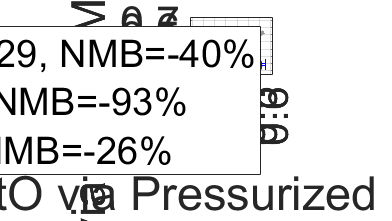

%%%%%%%%%%%%%%%%%%%%%%
%%%SUPPLEMENTAL
%%%compare SDK passive with pressurized, Picarro, and AROMA
%%%%%%%%%%%%%%%%%%%%%%

%colors: passive, STER, SSG, pressurized, picarro
colorSTER = [0.769, 0.080, 0.557];
colorSSG = [0.071, 0.74, 0.74];
colors = [1, 0, 0; colorSTER; colorSSG; 0, 0, 1; 0, 0, 0;];
legPre = ["Pressurized, n=", "Picarro, n=", "AROMA, n="];

fig = figure('Position', get(0, 'Screensize')); %for saving the figure
hold on
grid on
box on
ax = gca;
pbaspect([1.4, 1, 1])

%1:1 line
plot([-1, 5], [-1, 5], '--', 'color', [0.6 0.6 0.6], 'linewidth', 3)

%passive
xError = compareCollocated.EntATEC.std1;
xError(xError == 0) = nan;
yError = compareCollocated.EntATEC.std2;
yError(yError == 0) = nan;
errorbar(compareCollocated.EntATEC.avg1, compareCollocated.EntATEC.avg2, yError, yError, xError, xError, ...
    'o', 'MarkerEdgeColor', colors(4, :), 'MarkerFaceColor', colors(4, :), ...
    'MarkerSize', 15.5, 'Color', colors(4, :))

%picarro
xError = compareCollocated.EntPic.std1;
xError(xError == 0) = nan;
yError = compareCollocated.EntPic.std2;
yError(yError == 0) = nan;
errorbar(compareCollocated.EntPic.avg1, compareCollocated.EntPic.avg2, yError, yError, xError, xError, ...
    '^', 'MarkerEdgeColor', colors(5, :), 'MarkerFaceColor', colors(5, :), ...
    'MarkerSize', 15.5, 'Color', colors(5, :))

%AROMA
xError = compareCollocated.EntAROMA.std1;
xError(xError == 0) = nan;
yError = compareCollocated.EntAROMA.std2;
yError(yError == 0) = nan;
errorbar(compareCollocated.EntAROMA.avg1, compareCollocated.EntAROMA.avg2, yError, yError, xError, xError, ...
    'square', 'MarkerEdgeColor', [0.8392, 0.5686, 0.3098], 'MarkerFaceColor', [0.8392, 0.5686, 0.3098], ...
    'MarkerSize', 16.5, 'Color', [0.8392, 0.5686, 0.3098])


%%lims
offset = 0.02;
xlim([-0.1 - offset*0.5, 0.6 + offset*0.5])
ylim([-0.05 - offset*0.68/1.4, 0.73 + offset*0.68])
xticks(-0.1:0.1:0.6)
yticks(0:0.1:0.7)

%%labels
ax.FontSize = 32;
xlabel("EtO via Pressurized (ppb)")
ylabel("EtO via Other Method (ppb)")

%%legend
legStr = [""];
legItems = {'EntATEC', 'EntPic', 'EntAROMA'};
for i = 1:length(legPre)
    temp = statsCollocatedComparison.(legItems{i});
    legStr(i) = strcat(legPre(i), num2str(temp.n), ", r=", sprintf("%0.2f", round(temp.r, 2)), ...
        ", NMB=", sprintf("%0.0f", round(temp.NMB)), "%");
end
legend(["", legStr(1:3)])


hold off

% %%export the figure
% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Sup intercomparisons.png";
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again

% cd ..\Data